# week 13 

11/29    HW: kmeans, fcm, gaussian mixture model, region growing (load MRI, V)

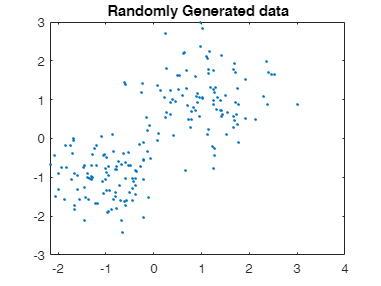

clear all;
X = [randn(100,2)*.75 + ones(100,2); randn(100,2)*0.5 - ones(100,2)];
figure; plot(X(:,1), X(:,2),'.');
title 'Randomly Generated data';


[idx, C] = kmeans(X, 2);
x1 = find(idx==1);
x2 = find(idx==2);
disp(C);

    1.0730    1.0764
   -0.9766   -0.9798



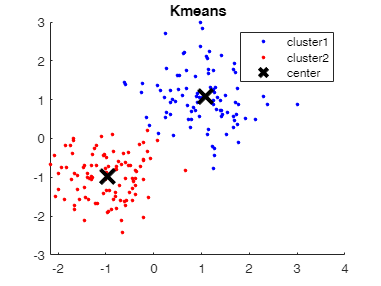

figure;
hold on;
title 'Kmeans';
plot(X(x1,1), X(x1,2),'.', ...
    'MarkerSize',8, 'Color','blue');
plot(X(x2,1), X(x2,2),'.', ...
    'MarkerSize',8, 'Color','red');
plot(C(:,1),C(:,2),'kx',...
     'MarkerSize',15,'LineWidth',3)
legend('cluster1', 'cluster2', 'center');
hold off;

FCM

[centers, U] = fcm(X, 2);

Iteration count = 1, obj. fcn = 364.773913
Iteration count = 2, obj. fcn = 288.857288
Iteration count = 3, obj. fcn = 269.417410
Iteration count = 4, obj. fcn = 188.256389
Iteration count = 5, obj. fcn = 139.208284
Iteration count = 6, obj. fcn = 136.489110
Iteration count = 7, obj. fcn = 136.443191
Iteration count = 8, obj. fcn = 136.442501
Iteration count = 9, obj. fcn = 136.442486
Iteration count = 10, obj. fcn = 136.442485


x1 = find(U(1,:) >= 0.5);
x2 = find(U(2,:) > 0.5);
disp(centers);

   -0.9788   -0.9801
    1.1061    1.0943



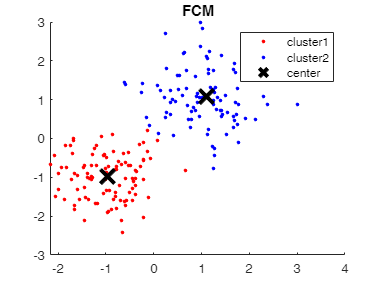

figure;
hold on;
plot(X(x1,1), X(x1,2),'.', ...
    'MarkerSize',8,'Color','red');
plot(X(x2,1), X(x2,2),'.', ...
    'MarkerSize',8,'Color','blue');
plot(centers(:,1),centers(:,2),'kx',...
     'MarkerSize',15,'LineWidth',3)
legend('cluster1', 'cluster2', 'center');
title 'FCM'
hold off;

gaussian mixture model

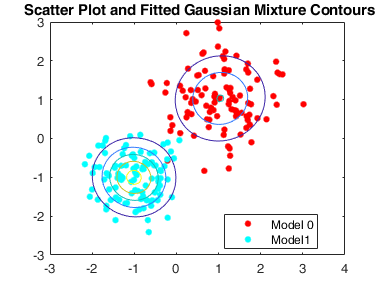

GMModel = fitgmdist(X, 2);
figure
y = [zeros(100,1);ones(100,1)];
h = gscatter(X(:,1),X(:,2),y);
hold on
gmPDF = @(x,y) arrayfun(@(x0,y0) pdf(GMModel,[x0 y0]),x,y);
g = gca;
fcontour(gmPDF,[g.XLim g.YLim])
title('{\bf Scatter Plot and Fitted Gaussian Mixture Contours}')
legend(h,'Model 0','Model1')
hold off

Region growing

load MRI, maybe add some noise and seperate WM and GM

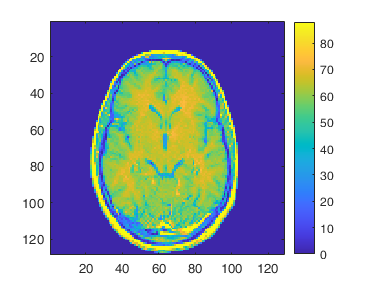

load mri.mat;
D = squeeze(D);D = D(:,:,12);
imagesc(D);colorbar;axis square;

% region growing